# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** : 이제성**

**학번**** : 201716272**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/Jeseong22/Digital-signal-process**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

x = [1,2,2,1];
N=4;
X=dft(x,N);
magX= abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


ix = idft(x,N)

ix =    1.5000 + 0.0000i  -0.2500 + 0.2500i   0.0000 + 0.0000i  -0.2500 - 0.2500i


a = 0:3;
ad = 1 + 2*exp(-j*a) + 2*exp(-j*2*a) + exp(-j*3*a);
magX1= abs(ad), phaX1 = angle(ad)*180/pi

magX1 =     6.0000    3.6518    0.1812    0.1386


phaX1 =          0  -85.9437 -171.8873  -77.8310


2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.


x0=[1,2,2,1,0,0,0,0,0,0,0,0,0,0,0,0];
N0=16;
X0=dft(x,N);
magX0= abs(X0), phaX0 = angle(X0)*180/pi

magX0 =     6.0000    1.4142    0.0000    1.4142


phaX0 =          0 -135.0000  -90.0000  135.0000


2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$


xn2 = [4,1,-1,1]; N2= 4; Xk2 = dfs(xn2,N2)

Xk2 =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


x20 = 5;
x21 = 4-j+1+j

x21 = 5

x22 = 4-1-1-1

x22 = 1

x23 = 4+j+1-j

x23 = 5

2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$


xn22 = [1,0,-1,-1,0]; N22= 5; Xk22 = dfs(xn22,N22)

Xk22 =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


x220 = 1+0-1-1+0

x220 = -1

x221 = 1-exp(-j*4*pi/5)-exp(-j*6*pi/5)

x221 = 2.6180 + 0.0000i

x222 = 1-exp(-j*8*pi/5)-exp(-j*12*pi/5)

x222 = 0.3820 - 0.0000i

x223 = 1-exp(-j*12*pi/5)-exp(-j*18*pi/5)

x223 = 0.3820 - 0.0000i

x224 = 1-exp(-j*16*pi/5)-exp(-j*24*pi/5)

x224 = 2.6180 + 0.0000i

3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

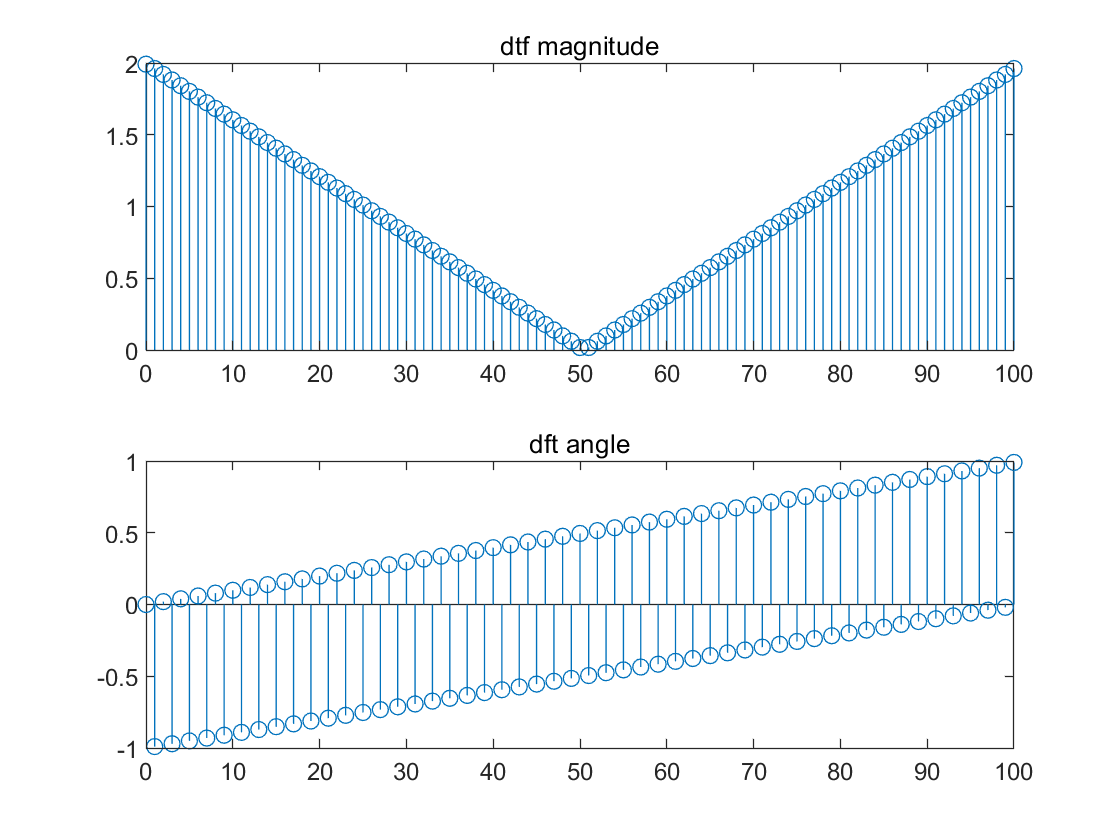


n3 = [0:100];
k3 = [0:100];
xn3 = sinc((n3-50)/2).^2;
Xk3=dft(xn3,length(n3));

figure(1)
subplot(2,1,1);
stem(k3,abs(Xk3));
title("dtf magnitude");

subplot(2,1,2);
stem(k3,angle(Xk3)/pi);
title("dft angle");

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

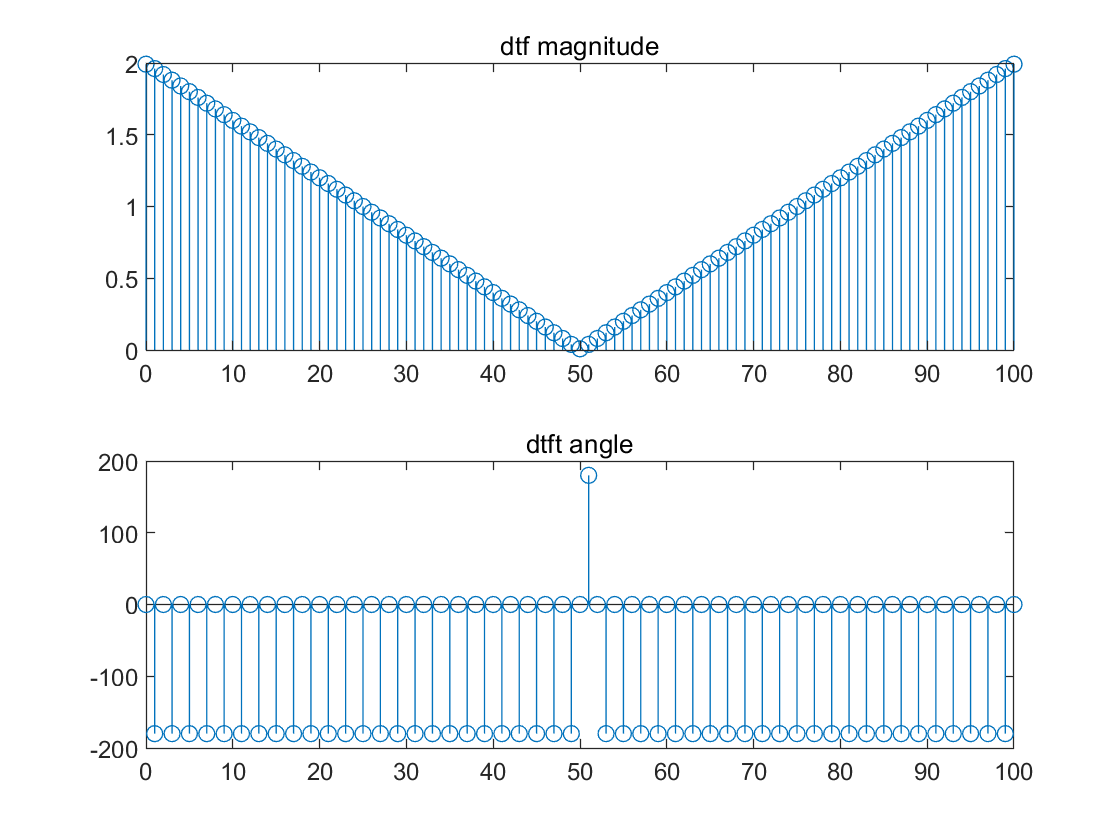


n32=[0:100];
xn32 = sinc((n32-50)/2).^2;
k32=[0:10:1000];
w32=(pi/500)*k32;
Xk32=xn32*(exp(-j*pi/500)).^(n32'*k32);

figure(2)
subplot(2,1,1);
stem(k32/10,abs(Xk32));
title("dtf magnitude");
subplot(2,1,2);
stem(k32/10,angle(Xk32)*180/pi);
title("dtft angle");

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

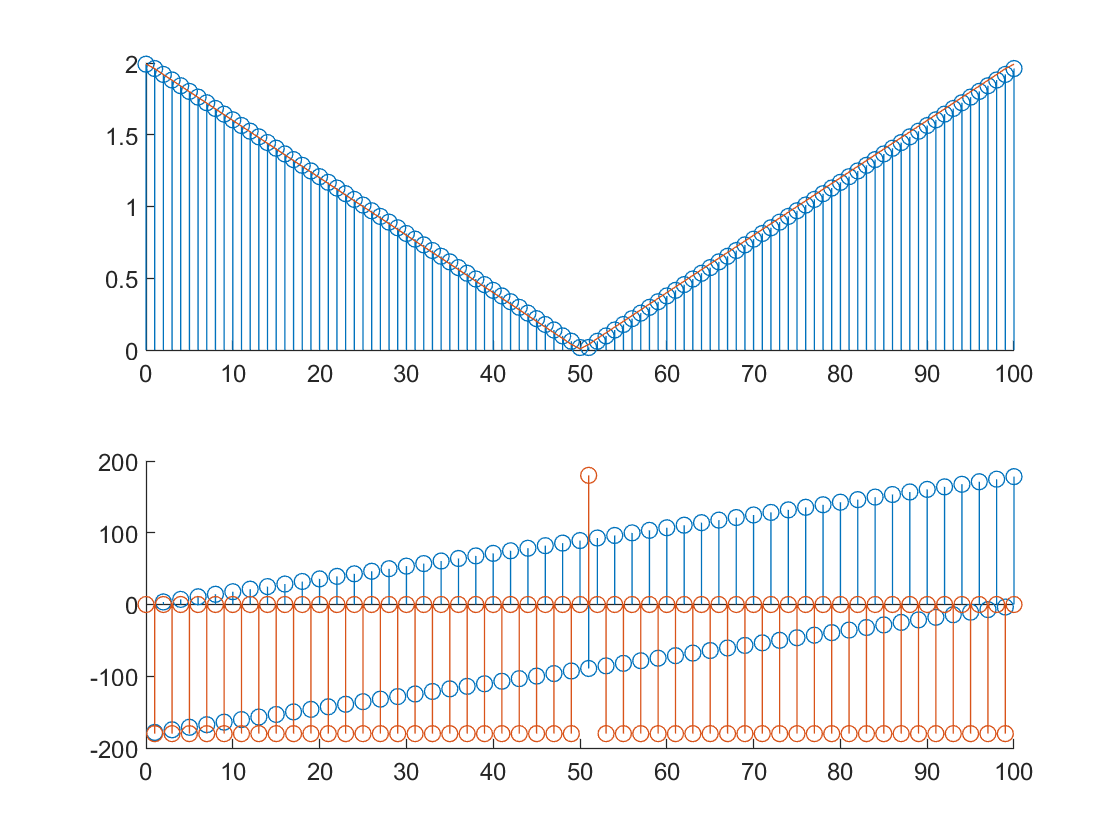


n33 = [0:100]; 
xn33 = sinc((n33-50)/2).^2; 
N33 = length(xn33); 
Xk33 = dft(xn33,N33); 
k33 = [0:N33-1]; 
mag33 = abs(Xk33); 
angle33 = angle(Xk33)*180/pi;

figure(3)
subplot(2,1,1);
hold on 
stem(k33,mag33); 
subplot(2,1,2); 
hold on
stem(k33,angle33); 
subplot(2,1,1);
plot(k33,abs(Xk32));
hold off
subplot(2,1,2);
stem(k33,angle(Xk32)*180/pi);
hold off

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

정답: 유한시간에서 샘플의 개수가 신호의 개수보다 크거나 같으면 신호를 다시 재구성 할 수 있음으로 신호의 개수가 101개, 샘플의 개수가 101개 임으로 재구성이 가능하다 .



function [Xk] = dft(xn,N)
n = [0:N-1];
k = [0:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn* WNnk;

end

function [xn] = idft(Xk,N)
n=[0:N-1];
k=[0:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end


function [Xk] = dfs(xn,N)
n = [0:N-1];
k = [0:N-1];
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn* WNnk;

end
